### Computational Methods in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Direct Methods for Solving Systems of Linear Equations

**Learning outcomes**

On successful completion of this page readers will be able to:

- Apply LU decomposition to factorise a square matrix into a product of a lower triangular and upper triangular matrices.

- Apply Crout's method for solving a system of linear equations using LU decomposition.

- Solve a system of linear equations using LU decomposition with partial pivoting.

- Apply Cholesky decomposition to factorise a positive definite matrix into a product of a lower triangular matrix and its transpose.

- Solve a system of linear equations using the Cholesky-Crout method.

- Apply QR decomposition to factorise an $m\times n$ matrix into the product of an orthogonal matrix and an upper triangular matrix.

- Solve a systems of linear equations using QR decomposition.

## Systems of linear equations

Linear systems of equations appear often in the topics of numerical analysis and numerical solutions to differential equations. The methods that are applied to solve systems of linear equations fall into one of two categories: **direct methods** that use an algebraic approach and **indirect methods** that use an iterative approach. On this page we will look at some common direct methods.

A [**system of linear equations**](https://en.wikipedia.org/wiki/System_of_linear_equations) with $m$ equations and $n$ unknowns can be expressed as


$$\,\,\,a_{11} x_1 + a_{12} x_2 + \cdots + a_{1n} x_n = b_1, \\
\,\,\,a_{21} x_1 + a_{22} x_2 + \cdots + a_{2n} x_n = b_2, \\
\,\,\,\,\,\qquad\qquad\qquad\qquad\qquad\,\, \vdots \\
a_{m1} x_1 + a_{m2}x_2 + \cdots + a_{mn}x_n = b_n,$$


where $x_i$ are the unknowns, $a_{ij}$ are coefficients and $b_i$ are constant terms. It is often more convenient to express a system of linear equations as a matrix equation. Let $[A]_{ij} = a_{ij}$ be the **coefficient matrix**, $\mathbf{x} = (x_1, x_2, \ldots, x_m)^T$ be the **unknown vector** and $\mathbf{b}=(b_1, b_2, \ldots, b_m)^T$ be the **constant vector** then we can rewrite a system of linear equations as $A\mathbf{x}=\mathbf{b}$, i.e.,


$$\pmatrix{
a_{11} & a_{12} & \cdots & a_{1n} \cr
a_{21} & a_{22} & \cdots & a_{2n} \cr
\vdots & \vdots & \ddots & \vdots \cr
a_{m1} & a_{m2} & \cdots & a_{mn}}
\pmatrix{ x_1 \cr x_2 \cr \vdots \cr x_m} =
\pmatrix{ b_1 \cr b_2 \cr \vdots \cr b_m}.$$


## LU decomposition

[**LU decomposition**](https://en.wikipedia.org/wiki/LU_decomposition) (also known as **LU factorisation**) is a procedure for factorising a square matrix $A$ into the product of a **lower triangular** matrix $L$ and an **upper triangular** matrix $U$ such that

$A=LU$.

The advantage of writing a matrix as a product of $L$ and $U$ is that the solution to a triangular set of equations is easy to calculate using forward and back substitution.

Consider the LU decomposition of a $3\times 3$ matrix


$$\pmatrix{ a_{11} & a_{12} & a_{13} \cr a_{21} & a_{22} & a_{32} \cr a_{31} & a_{32} & a_{33} } =
\pmatrix{ \ell_{11} & 0 & 0 \cr \ell_{21} & \ell_{22} & 0 \cr \ell_{31} & \ell_{32} & \ell_{33}}
\pmatrix{ u_{11} & u_{12} & u_{13} \cr 0 & u_{22} & u_{23} \cr 0 & 0 & u_{33}},$$


which gives a system of 9 equations (one for each element in $A$) in 12 unknowns which has an infinite number of solutions. If we use the condition $\ell_{ii}=1$ then


$$\pmatrix{a_{11} & a_{12} & a_{13} \cr a_{21} & a_{22} & a_{23} \cr a_{31} & a_{32} & a_{33}} = 
\pmatrix{
u_{11} & u_{12} & u_{13} \cr
\ell_{21}u_{11} & \ell_{21}u_{12} + u_{22} & \ell_{21}u_{13} + \ell_{22}u_{23} \cr
\ell_{31}u_{11} & \ell_{31}u_{12} + \ell_{32}u_{22} & \ell_{31}u_{13} + \ell_{32}u_{23} + \ell_{33}u_{33}}
} .$$


The elements in the lower triangular region $(i>j)$ are


$$a_{ij} = \sum_{k=1}^j \ell_{ik}u_{kj}=\ell_{ij}u_{jj}+ \sum_{k=1}^{j-1}\ell_{ik}u_{kj},$$


which is rearranged to


$$\ell_{ij} = \frac{1}{u_{jj}}\left(a_{ij} - \sum_{k=1}^{j-1} \ell_{ik}u_{kj}\right). \qquad \qquad (1)$$


For the elements in the upper triangular region $(i\leq j)$ we have


$$a_{ij} = u_{ij} + \sum_{k=1}^{i-1} \ell_{ik}u_{kj},$$


which is rearranged to 


$$u_{ij} = a_{ij} - \sum_{k=1}^{i-1} \ell_{ik}u_{kj}. \qquad \qquad (2)$$


So to calculate the LU decomposition of a square matrix $A$ we loop through each column of $A$ and calculate the elements of $L$ and $U$ for that column using equations (1) and (2), i.e., 


$$u_{ij} = a_{ij} - \sum_{k=1}^{i-1} \ell_{ik}u_{kj}, \qquad \qquad i = 1, 2, \ldots, j, \qquad \qquad \quad \,\,\,\,(3)\\
\ell_{ij} = \begin{cases} 
1, & i = j,\\ 
\frac{1}{u_{jj}}\left(a_{ij}-\sum_{k=1}^{j-1} \ell_{ik}u_{kj}\right), & i =j+1, j+2, \ldots, n 
\end{cases}  \qquad (4) $$


#### Example 1

Determine the LU decomposition of the following matrix


$$A = \pmatrix{1 & 3 & 0 \cr 2 & -4 & -1 \cr -3 & 1 & 2}.$$


Stepping through the columns of $A$


$$\begin{array}{ll}
j = 1: \qquad & u_{11} = a_{11} = 1, \\
& \ell_{21} = \frac{1}{u_{11}}(a_{21}) = \frac{1}{1}(2)=2, \\
& \ell_{31} = \frac{1}{u_{11}}(a_{31}) = \frac{1}{1}(-3) = -3, \\
j = 2: & u_{12} = a_{12} = 3, \\
& u_{22} = a_{22} - \ell_{21}u_{12} = -4 - 2(3) = -10, \\
& \ell_{32} = \frac{1}{u_{22}}(a_{32} - \ell_{31}u_{12}) = \frac{1}{-10}(1 + 3(3)) = 1, \\
j = 3: & u_{13} = a_{13} = 0, \\
& u_{23} = a_{23} - \ell_{21}u_{13} = -1 -2(0) = -1, \\
& u_{33} = a_{33} - \ell_{31}u_{13} - \ell_{32}u_{23} = 2 + -3(0) - 1(-1)=3.
\end{array}$$


Therefore


$$L = \pmatrix{1 & 0 & 0 \cr 2 & 1 & 0 \cr -3 & -1 & 1}, \qquad
U = \pmatrix{1 & 3 & 0 \cr 0 & -10 & -1 \cr 0 & 0 & 1}.$$


Checking that $LU=A$


$$\pmatrix{1 & 0 & 0 \cr 2 & 1 & 0 \cr -3 & -1 & 1}
\pmatrix{1 & 3 & 0 \cr 0 & -10 & -1 \cr 0 & 0 & 1} =
\pmatrix{1 & 3 & 0 \cr 2 & -4 & -1 \cr -3 & 1 & 2}.$$


#### Example 2

The function called lu_decomp below is defined in the Functions section at the bottom of this page calculates the LU decomposition of a square matrix `A`. Note that I haven't used the more sensible name `lu` since this is already used for [MATLAB's LU decomposition function](https://uk.mathworks.com/help/matlab/ref/lu.html).

The code below uses the function lu_decomp to calculate the LU decomposition of the matrix from example 1.

% Define matrix A
A = [ 1, 3, 0 ;
      2, -4, -1 ;
     -3, 1, 2 ];

% Calculate L and U
[L, U] = lu_decomp(A);

% Output and check results
for i = 1 : 1
    A
    L
    U
    LU = L * U
end

A =      1     3     0
     2    -4    -1
    -3     1     2


L =      1     0     0
     2     1     0
    -3    -1     1


U =      1     3     0
     0   -10    -1
     0     0     1


LU =      1     3     0
     2    -4    -1
    -3     1     2


## Crout's method

Given a system of linear equations of the form $A\mathbf{x}=\mathbf{b}$ then the solution can be calculated using the LU decomposition of $A$ using **Crout's method**. Since $A=LU$ then


$$LU\mathbf{x} = \mathbf{b}$$


Let $\mathbf{y}=U\mathbf{x}$ then


$$L \mathbf{y} = \mathbf{b}.$$


$L$ is lower triangular so the solution for $L\mathbf{y}=\mathbf{b}$ is easily calculated using forward substitution. Once $\mathbf{y}$ has been calculated the solution to $U\mathbf{x}=\mathbf{y}$ is calculated using back substitution.

The advantage of using Crout's method is that once the LU decomposition of the coefficient matrix has been calculated the can be used for any values of the right-hand side vector $\mathbf{b}$ unlike Gaussian elimination where row reduction will need to be repeated for difference values of $\mathbf{b}$.

#### Example 3

Use Crout's method to solve the following system of linear equations


$$\pmatrix{1 & 3 & 0 \cr 2 & -4 & -1 \cr -3 & 1 & 2}\pmatrix{x_1 \cr x_2 \cr x_3}=\pmatrix{-7 \cr 11 \cr 1}.$$


We saw in example 1 that the LU decomposition of the coefficient matrix is


$$L = \pmatrix{1 & 0 & 0 \cr 2 & 1 & 0 \cr -3 & -1 & 1}, \qquad
U = \pmatrix{1 & 3 & 0 \cr 0 & -10 & -1 \cr 0 & 0 & 1}.$$


Solving $L\mathbf{y}=\mathbf{b}$


$$\pmatrix{1 & 0 & 0 \cr 2 & 1 & 0 \cr -3 & -1 & 1} \pmatrix{y_1 \cr y_2 \cr y_3} = \pmatrix{-7 \cr 11 \cr 1},$$


gives


$$y_1 = -7, \\
y_2 = 11 - 2y_1 = -2(-7)=25, \\
y_3 = -1 + 3y_1 + y_2 = -1 + 3(-7) + 1(25) = 5.$$


Solving $U\mathbf{x} = \mathbf{y}$


$$\pmatrix{1 & 3 & 0 \cr 0 & -10 & -1 \cr 0 & 0 & 1} \pmatrix{x_1 \cr x_2 \cr x_3} = \pmatrix{-7 \cr 25 \cr 5},$$


gives


$$x_3 = \frac{1}{1}x_3 = 5, \\
x_2 = \frac{1}{-10}(25+x_3) = -\frac{1}{10}(25+5) = -3, \\
x_1 = \frac{1}{1}(-7-0x_3 -3x_2)=-7+9=2.$$


So the solution is $\mathbf{x}=(2, -3, 5)$.

#### Example 4

The function called crout below is defined in the Functions section at the bottom of the page and calculate the solution to the system of linear equations $LU\mathbf{x}=\mathbf{b}$ using Crout's method.

The function `crout` uses the functions forward_sub and back_sub shown below (also defined in the Functions section) which perform forward and back substitution.

The code below uses the function `crout` to solve the system of linear equations from example 3.

clear

% Define system of linear equations
A = [ 1, 3, 0 ;
      2, -4, -1 ;
     -3, 1, 2 ];
b = [ -7 ; 11 ; 1 ];

% Calculate LU decomposition of A
[L, U] = lu_decomp(A);

% Calculate solution to Ax = b using Crout's method
x = crout(L, U, b);

% Output results
for i = 1 : length(x)
    fprintf('x_%1i = %1.4f\n', i, x(i))
end

x_1 = 2.0000
x_2 = -3.0000
x_3 = 5.0000


### Partial pivoting

A problem that can be encountered with LU decomposition is that if the value of $u_{jj}$ in equation (1) is zero or some small number it will mean that $\ell_{ij}$ is undefined or prone to computational rounding errors due to the resulting value being very large (this is known as an [ill-conditioned system](https://en.wikipedia.org/wiki/Condition_number)).

This problem can be overcome by using [**partial pivoting**](https://en.wikipedia.org/wiki/Pivot_element#Partial_and_complete_pivoting) where rows of the coefficient matrix are permuted so that the pivot element on the main diagonal is the larger than the elements in the column beneath it. The permutations applied to the coefficient matrix are recorded in a matrix $P$ which is determined by applying the same permutations to the identity matrix.

#### Example 5

Apply partial pivoting the following matrix and determine the permutation matrix $P$


$$A = \pmatrix{0 & 1 & -2 \cr 1 & 0 & 2 \cr 3 & -2 & 2}.$$


Using row operations


$$\pmatrix{0 & 1 & -2 \cr 1 & 0 & 2 \cr 3 & -2 & 2} R_1 \leftrightarrow R_3 
\qquad \longrightarrow \qquad 
\pmatrix{3 & -2 & 2 \cr 1 & 0 & 2 \cr 0 & 1 & -2} R_2 \leftrightarrow R_3
\qquad \longrightarrow \qquad
\pmatrix{3 & -2 & 2 \cr 0 & 1 & -2 \cr 1 & 0 & 2}.$$


Apply the same row operations to the identity matrix


$$\pmatrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 1} R_1 \leftrightarrow R_3 
\qquad \longrightarrow \qquad 
\pmatrix{0 & 0 & 1 \cr 0 & 1 & 0 \cr 1 & 0& 0} R_2 \leftrightarrow R_3
\qquad \longrightarrow \qquad
\pmatrix{0 &0 & 1 \cr 1 & 0 & 0 \cr 0 & 1 & 0 }.$$


So $P = \pmatrix{0 &0 & 1 \cr 1 & 0 & 0 \cr 0 & 1 & 0 }$. Note that $PA$ gives the matrix $A$ after partial pivoting has been applied i.e., 


$$\pmatrix{0 & 0 & 1 \cr 1 & 0 & 0 \cr 0 & 1 & 0} \pmatrix{0 & 1 & -2 \cr 1 & 0 & 2 \cr 3 & -2 & 2} = \pmatrix{3 & -2 & 2 \cr 0 & 1 & -2 \cr 1 & 0 & 2}.$$


#### Example 6

The function called partial_pivot below is defined in the Functions section at the bottom of this page and calculates the permutation matrix $P$ for applying partial pivoting to the square matrix `A`. 

The code below uses the function `partial_pivot` to compute the permutation matrix $P$ for the matrix $A$ from example 5.

clear

% Define A matrix
A = [ 0, 1, -2 ;
      1, 0, 2 ;
      3, -2, 2 ];

% Calculate permutation matrix P
P = partial_pivot(A);
P

P =      0     0     1
     1     0     0
     0     1     0


### LU decomposition with partial pivoting

To calculate **LU decomposition with partial pivoting** uses the process as before with the exception that the coefficient matrix has partial pivoting applied prior to the calculation of $L$ and $U$, i.e.,


$$LU=PA.$$


Using partial pivoting on the coefficient matrix $A$ when solving the system of linear equations $A\mathbf{x}=\mathbf{b}$ results in


$$PA\mathbf{x} = \mathbf{b},$$


and since $P^{-1}=P$ (the inverse operation of swapping any two rows is to simply swap them back) then


$$A\mathbf{x} = P\mathbf{b}.$$


So Crout's method when using LU decomposition with partial pivoting requires solving the following for $\mathbf{y}$ and $\mathbf{x}$


$$L\mathbf{y} = P\mathbf{b}, \\ U \mathbf{x} = \mathbf{y}.$$


#### Example 7

Solve the following system of linear equations using Crout's method with LUP decomposition


$$\pmatrix{0 & 1 & -2 \cr 1 & 0 & 2 \cr 3 & -2 & 2} \pmatrix{x_1 \cr x_2 \cr c_3} = \pmatrix{10 \cr -4 \cr -8}.$$


We have seen from example 5 that applying partial pivoting to the coefficient matrix results in


$$A = \pmatrix{ 3 & -2 & 2 \cr 0 & 1 & -2 \cr 1 & 0 & 2}, \qquad P = \pmatrix{0 & 0 & 1 \cr 1 & 0 & 0 \cr 0 & 1 & 0 }.$$


Calculating the LU decomposition of $A$ using equations (3) and (4)


$$\begin{array}{ll}
j = 1: & u_{11} = a_{11} = 3, \\
& \ell_{21} = \frac{1}{u_{11}}a_{21} = \frac{1}{3}(0)= 0,\\
& \ell_{31} = \frac{1}{u_{11}}a_{31} = \frac{1}{3}(1) = \frac{1}{3}, \\
j = 2: & u_{12} = a_{12} = -2, \\
& u_{22} = a_{22} - \ell_{21}u_{12} = 1 - 0 (-2) = 1, \\
& \ell_{32} = \frac{1}{u_{22}}(a_{32} - \ell_{31}u_{12}) = \frac{1}{1}\left(0 - \frac{1}{3}(-2)\right) = \frac{2}{3}, \\
j = 3 : & u_{13} = a_{13} = 2, \\
& u_{23} = a_{23} - \ell_{21}u_{12} = -2 -0(-2)=-2, \\
& u_{33} = a_{33} - \ell_{31}u_{13} - \ell_{32}u_{23} = 2 - \frac{1}{3}(2) - \frac{2}{3}(-2) = \frac{8}{3}.
\end{array}$$


Therefore


$$L = \pmatrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr \frac{1}{3} & \frac{2}{3} & 1}, \qquad R = \pmatrix{3 & -2 & 2 \cr 0 & 1 & -2 \cr 0 & 0 & \frac{8}{3}}.$$


Solving $L\mathbf{y} = P\mathbf{b}$ using forward substitution 


$$\pmatrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr \frac{1}{3} & \frac{2}{3} & 1} \pmatrix{y_1\cr y_2\cr y_3} = \pmatrix{0 & 0 & 1 \cr 1 & 0 & 0 \cr 0 & 1 & 0} \pmatrix{10 \cr -4 \cr -8} = \pmatrix{-8 \cr 10 \cr -4},$$


gives


$$y_1=-8 \\ y_2 = 10-0(8) = 10, \\ y_3 = -4 - \frac{1}{3}(8) + \frac{2}{3}(10) = -8.$$


Solving $U\mathbf{x} = \mathbf{y}$ using back substitution


$$\pmatrix{ 3 & -2 & 2 \cr 0 & 1 & -2 \cr 0 & 0 & \frac{8}{3}} \pmatrix{x_1 \cr x_2 \cr x_3} = \pmatrix{-8 \cr 10 \cr -8},$$


gives


$$x_3 = \frac{3}{8}(-8)=-3, \\ x_2 = \frac{1}{1}(10 + 2(-3)) = 4, \\ x_1 = \frac{1}{3}(-8 + 2(4) -2(-3)) = 2.$$


So the solution is $\mathbf{x}=(2, 4, -3)$.

#### Example 8

The code below uses the previously defined functions `partial_pivot`, lu_decomp and `crout` to solve the system of linear equations from example 7 using LU decomposition with partial pivoting.

clear

% Define system of linear equations
A = [ 0, 1, -2 ;
      1, 0, 2 ;
      3, -2, 2 ];
b = [ 10 ; -4 ; -8 ];

% Calculate permutation matrix P
P = partial_pivot(A);

% Calculate LU decomposition of PA
[L, U] = lu_decomp(P * A);

% Use Crout's method to solve LUx = Pb
x = crout(L, U, P * b);

% Output results
for i = 1 : length(x)
    fprintf('x_%1i = %1.4f\n', i, x(i))
end

x_1 = 2.0000
x_2 = 4.0000
x_3 = -3.0000


## Cholesky decomposition

[Cholesky decomposition](https://en.wikipedia.org/wiki/Cholesky_decomposition) is an efficient decomposition method that can be used when a square matrix is [**positive definite**](https://en.wikipedia.org/wiki/Definite_symmetric_matrix).

**Definition (positive definite matrix)**

A symmetric square matrix $A$ is said to be positive definite if $\mathbf{x}^T A \mathbf{x}$ is positive for a non-zero column vector $\mathbf{x}$. 

Given a positive definite matrix $A$ then Cholesky decomposition factorises $A$ into the product of a lower triangular matrix $L$ and its transpose, i.e.,


$$A = LL^T.$$


Consider the Cholesky decomposition of a $3\times 3$ matrix


$$\pmatrix{ a_{11} & a_{12} & a_{13} \cr a_{21} & a_{22} & a_{23} \cr a_{31} & a_{32} & a_{33}} =
\pmatrix{\ell_{11} & 0 & 0 \cr \ell_{21} & \ell_{22} & 0 \cr \ell_{31} & \ell_{32} & \ell_{33}} 
\pmatrix{ \ell_{11} & \ell_{21} & \ell_{31} \cr 0 & \ell_{22} & \ell_{32} \cr 0 & 0 & \ell_{33}} =
\pmatrix{ \ell_{11}^2 & \ell_{11}\ell_{21} & \ell_{11} \ell_{31} \cr \ell_{11}\ell_{21} & \ell_{21}^2 + \ell_{22}^2 & \ell_{21}\ell_{31} + \ell_{22}\ell_{33} \cr \ell_{11} \ell_{31} & \ell_{21}\ell_{31} + \ell_{22}\ell_{33} & \ell_{31}^2 + \ell_{32}^2 + \ell_{33}^2}.$$


The elements on the main diagonal are


$$a_{jj} = \ell_{jj}^2 + \sum_{k=1}^{j-1} \ell_{jk}^2,$$


and the other elements are


$$a_{ij} = \sum_{k=1}^j \ell_{ik}\ell_{jk} = \ell_{jj}\ell_{ij} + \sum_{k=1}^{j-1} \ell_{ik}\ell_{jk}.$$


Rearranging these two expressions gives


$$\ell_{ij} = \begin{cases}
\sqrt{a_{ii} - \sum_{k=1}^{j-1} \ell_{jk}^2}, & i= j, \\
\frac{1}{\ell_{jj}}\left( a_{ij} - \sum_{j=1}^{i-1} \ell_{ik}\ell_{jk}\right), & j = i + 1, \ldots, n.
\end{cases}$$


#### Example 9

Calculate the Cholesky decomposition of the following matrix


$$A = \pmatrix{ 4 & -2 & -4 \cr -2 & 10 & 5 \cr -4 & 5 & 14}.$$


Stepping through the columns of $A$


$$\begin{array}{ll}
j=1 : & \ell_{11} = \sqrt{a_{11}} = \sqrt{4} = 2, \\
& \ell_{21} = \frac{1}{\ell_{11}}(a_{21}) = \frac{1}{2}(-2) =-1, \\
& \ell_{31} = \frac{1}{\ell_{11}}(a_{31}) = \frac{1}{2}(-4) = -2, \\
j=2: & \ell_{22} = \sqrt{a_{22} - \ell_{21}^2} = \sqrt{10 - (-1)^2} = \sqrt{9} = 3, \\
& \ell_{32} = \frac{1}{\ell_{22}}(a_{32} - \ell_{31}\ell_{21}) = \frac{1}{3}(5 - (-2)(-1)) = 1, \\
j = 3: & \ell_{33} = \sqrt{a_{33} - \ell_{31}^2 - \ell_{32}^2} = \sqrt{14 - (-2)^2 - 1^2} = \sqrt{9} = 3,
\end{array}$$


therefore $L = \pmatrix{2 & 0 & 0 \cr -1 & 3 & 0 \cr -2 & 1 & 3 }$. Checking that $A = LL^T$

$\pmatrix{ 2 & 0 & 0 \cr -1 & 3 & 0 \cr -2 & 1 & 3} \pmatrix{2 & -1 & -2 \cr 0 & 3 & 1 \cr 0 & 0 & 3} = \pmatrix{4 & -2 & -4 \cr -2 & 10 & 5 \cr -4 & 5 & 14}$.

#### Example 10

The function called `cholesky` below is defined in the Functions section at the bottom of this page calculates the Cholesky decomposition of the positive definite matrix `A`. 

The code below uses the function `cholesky` to calculate the Cholesky decomposition of the matrix from example 9. 

clear

% Define matrix A
A = [ 4, -2, -4 ;
     -2, 10, 5 ;
     -4, 5, 14 ];

% Calculate Cholesky decomposition
L = cholesky(A);

% Output and check results
for i = 1 : 1
    A
    L
    LLT = L * L';
    LLT
end

A =      4    -2    -4
    -2    10     5
    -4     5    14


L =      2     0     0
    -1     3     0
    -2     1     3


LLT =      4    -2    -4
    -2    10     5
    -4     5    14


### The Cholesky-Crout method

The [**Cholesky-Crout method**](https://en.wikipedia.org/wiki/Cholesky_decomposition#The_Cholesky%E2%80%93Banachiewicz_and_Cholesky%E2%80%93Crout_algorithms) is used to solve a system of linear equations of the form $A\mathbf{x} = \mathbf{b}$ where $A$ is a positive definite matrix.

Let $\mathbf{y} = L^T \mathbf{x}$ then since $A = LL^T$ then


$$\,\,\,\,L\mathbf{y} = \mathbf{b}, \\ L^T \mathbf{x} = \mathbf{y}.$$


#### Example 11

Solve the following system of linear equations using the Cholesky-Crout method.


$$\pmatrix{4 & -2 & -4 \cr -2 & 10 & 5 \cr -4 & 5 & 14} \pmatrix{x_1 \cr x_2 \cr x_3} = \pmatrix{-2 \cr 49 \cr 27}.$$


We saw in example 9 that $L=\pmatrix{2 & 0 & 0 \cr -1 & 3 & 0 \cr -2 & 1 & 3 }$. Solving $L\mathbf{y} = \mathbf{b}$


$$\pmatrix{2 & 0 & 0 \cr -1 & 3 & 0 \cr -2 & 1 & 3} \pmatrix{ y_1 \cr y_2 \cr y_3 } = \pmatrix{ -2 \cr 49 \cr 27},$$


gives


$$y_1 = \frac{-2}{2} = -1, \\ y_2 = \frac{1}{3}(49 + y_1) = \frac{1}{3}(49 - 1) = 16, \\ y_3 = \frac{1}{3}(27 + 2y_1 - y_2) = \frac{1}{3}(27 + 2(-1) -16) = 3.$$


Solving $L^T \mathbf{x} = \mathbf{y}$


$$\pmatrix{ 2 & -1 & -2 \cr 0 & 3 & 1 \cr 0 & 0 & 3 } \pmatrix{x_1 \cr x_2 \cr x_3} = \pmatrix{-1 \cr 16 \cr 3},$$


gives


$$x_3 = \frac{3}{3} = 1, \\ x_2 = \frac{1}{3}(16 - x_3) = \frac{1}{3}(16 - 1) = 5, \\ x_1 = \frac{1}{2}(-1 + x_2 + 2x_3) = \frac{1}{2}(-1 + 5 + 2(1)) = 3.$$


So the solution is $\mathbf{x}= (3, 5, 1)$.

#### Example 12

The code below using the functions `cholesky` and `crout` to solve the system of linear equations from example 11 using the Cholesky-Crout method.

clear

% Define linear system
A = [ 4, -2, -4 ;
     -2, 10, 5 ;
     -4, 5, 14 ];
b = [ -2 ; 49 ; 27 ];

% Calculate Cholesky decomposition
L = cholesky(A);

% Solve linear system using the Cholesky-Crout method
x = crout(L, L', b);

% Output results
for i = 1 : length(x)
    fprintf('x_%1i = %1.4f\n', i, x(i))
end

x_1 = 3.0000
x_2 = 5.0000
x_3 = 1.0000


## QR decomposition

The methods of LU and Cholesky decomposition can be used to solve a system of linear equations where the number of equations is the same as the number of unknowns so it has a single unique solution (if it exists). QR factorisation can be used to solve an [**overdetermined**](https://en.wikipedia.org/wiki/Overdetermined_system) system where the number of equations exceeds the number of unknowns. Overdetermined systems rarely have a unique solution but we can calculate an approximation that most closely satisfies all equations in the system.

The $m \times n$ coefficient matrix $A$ is factorised into the product of two matrices such that


$$A = QR,$$


where $Q$ is an orthogonal matrix and $R$ is an upper triangular matrix.

#### Definition (orthogonal vectors)

A set of vectors $\{ \mathbf{v}_1, \mathbf{v}_2, \mathbf{v}_3, \ldots \}$ is said to be **orthogonal** if $\mathbf{v}_i \cdot \mathbf{v}_j=0$ for $i \neq j$. Furthermore the set is said to be **orthonormal** if


$$\mathbf{v}_i \cdot \mathbf{v}_j = \begin{cases} 1, & i = j, \\ 0, & i \neq j. \end{cases}$$


#### Definition (orthogonal matrix)

An **orthogonal matrix** is a matrix where the columns are a set of orthonormal vectors. If $A$ is an orthogonal matrix if


$$A^TA= I.$$


#### Example 13

Show that the following matrix is an orthogonal matrix


$$A = \pmatrix{0.8 & -0.6 \cr 0.6 & 0.8 }.$$


Checking $A^TA=I$


$$A^TA = \pmatrix{0.8 & 0.6 \cr -0.6 & 0.8} \pmatrix{0.8 & -0.6 \cr 0.6 & 0.8} = \pmatrix{ 1 & 0 \cr 0 & 1 } = I.$$


So $A$ is an orthogonal matrix.

### Calculating QR decomposition using the Gram-Schmidt process

The calculation of the orthogonal matrix $Q$ can be achieved by using the [**Gram-Schmidt process**](https://en.wikipedia.org/wiki/Gram%E2%80%93Schmidt_process). Given a matrix consisting of $n$ linearly independent column vectors $A = (\mathbf{a}_1, \mathbf{a}_2, \ldots, \mathbf{a}_n)$ we wish to find a matrix that consists of 𝑛n orthogonal vectors $U  = (\mathbf{u}_1, \mathbf{u}_2, \ldots, \mathbf{u}_n)$ where the span of $U$ is that same as the span of $A$.

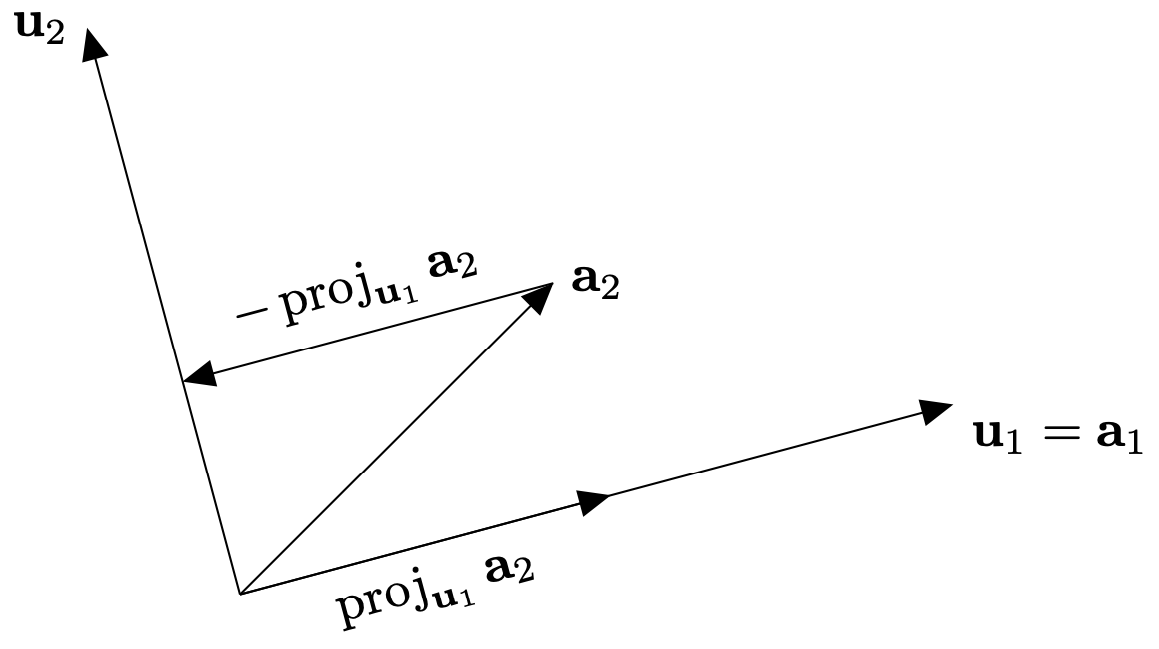

Consider the diagram above. Let $\mathbf{u}_1=\mathbf{a}_1$ then the vector $\mathbf{u}_2$ this is orthogonal to $\mathbf{u}_1$ can be found by subtracting the [**vector projection**](https://en.wikipedia.org/wiki/Vector_projection) of $\mathbf{a}_2$ onto $\mathbf{u}_1$, i.e., 


$$\mathbf{u}_2 = \mathbf{a}_2 - \text{proj}_{\mathbf{u}_1}(\mathbf{a}_2).$$


For the next vector $\mathbf{u}_3$ we want this to be orthogonal to both $\mathbf{u}_1$ and $\mathbf{u}_2$. To find $\mathbf{u}_3$ we subtract the projection of $\mathbf{a}_3$ onto $\mathbf{u}_1$ and $\mathbf{u}_2$ from $\mathbf{a}_3$. Doing similar for all vectors in $A$ we have


$$\begin{array}{ll}
\mathbf{u}_1 = \mathbf{a}_1, & \mathbf{q}_1 = \frac{\mathbf{u}_1}{\|\mathbf{u}_1\|}, \\
\mathbf{u}_2 = \mathbf{a}_2 - \text{proj}_{\mathbf{u}_1}(\mathbf{a}_2), & \mathbf{q}_2 = \frac{\mathbf{u}_2}{\|\mathbf{u}_2\|}, \\
\mathbf{u}_3 = \mathbf{a}_3 - \text{proj}_{\mathbf{u}_1}(\mathbf{a}_3) - \text{proj}_{\mathbf{u}_2}(\mathbf{a}_3), \qquad \qquad & \mathbf{q}_3 = \frac{\mathbf{u}_3}{\|\mathbf{u}_3\|}, \\
\quad \vdots & \quad  \vdots \\
\mathbf{u}_n = \mathbf{a}_n - \sum_{i=1}^{n-1} \text{proj}_{\mathbf{u}_i}(\mathbf{a}_n), & \mathbf{q}_n = \frac{\mathbf{u}_n}{\|\mathbf{u}_n\|}.
\end{array}$$


where $\mathbf{q}_i$ are orthonormal basis vectors. The vectors in $A$ can be expressed using the orthornomal basis $Q = (\mathbf{q}_1, \mathbf{q}_2, \ldots , \mathbf{q}_n)$


$$\mathbf{a}_1 = (\mathbf{q}_1 \cdot \mathbf{a}_1)\mathbf{q}_1, \\
\mathbf{a}_2 = (\mathbf{q}_1 \cdot \mathbf{a}_2)\mathbf{q}_1 + (\mathbf{q}_2 \cdot \mathbf{a}_2) \mathbf{q}_2, \\
\mathbf{a}_3 = (\mathbf{q}_1 \cdot \mathbf{a}_3) \mathbf{q}_1 + (\mathbf{q}_2 \cdot \mathbf{a}_3)\mathbf{q}_2 + (\mathbf{q}_3 \cdot \mathbf{a}_3)\mathbf{q}_3, \\
\quad \vdots \\
\mathbf{a}_n = \sum_{i=1}^n (\mathbf{q}_i \cdot \mathbf{a}_n) \mathbf{q}_i.$$


If $A = QR$ then


$$A = \pmatrix{\mathbf{q}_1 & \mathbf{q}_2 & \mathbf{q}_3 & \ldots & \mathbf{q}_5}
\pmatrix{
\mathbf{q}_1 \cdot \mathbf{a}_1 & \mathbf{q}_1 \cdot \mathbf{a}_2 & \mathbf{q}_1 \cdot \mathbf{a}_3 & \cdots & \mathbf{q}_1 \cdot \mathbf{a}_n \cr
0 & \mathbf{q}_2 \cdot \mathbf{a}_2 & \mathbf{q}_2 \cdot \mathbf{a}_3 & \cdots & \mathbf{q}_2 \cdot \mathbf{a}_n \cr
0 & 0 & \mathbf{q}_3 \cdot \mathbf{a}_3 & \cdots & \mathbf{q}_3 \cdot \mathbf{a}_n \cr
\vdots & \vdots & \vdots & \ddots & \vdots \cr
0 & 0 & 0 & \cdots & \mathbf{q}_n \cdot \mathbf{a}_n
}.$$


To calculate the QR decomposition of an $m\times n$ matrix $A$ using the Gram-Schmidt process we use the following steps.

For column 1 only:


$$r_{11} = \|\mathbf{a}_1\|, \\ \mathbf{q}_1 = \frac{\mathbf{a}_1}{r_{11}.$$


For all other columns $j=2,\ldots , n$ calculate


$$r_{ij} = \mathbf{q}_i \cdot \mathbf{a}_j, \qquad \qquad i = 1 , \ldots, j - 1, \\ \mathbf{u}_j = \mathbf{a}_j - \sum_{i=1}^{j-1} r_{ij}\mathbf{q}_i, \\ r_{jj} = \| \mathbf{u}_j \|, \\ \mathbf{q}_j = \frac{\mathbf{u}_j}{r_{jj}}.$$


#### Example 14

Calculate the QR decomposition of the following matrix using the Gram-Schmidt process


$$A = \pmatrix{ -1 & -1 & 1 \cr 1 & 3 & 3 \cr -1 & -1 & 5 \cr 1 & 3 & 7 }.$$


Column $j=1$:


$$r_{11} = \| \mathbf{a}_1 \| = 2, \\ 
\mathbf{q}_1 = \frac{\mathbf{a}_1}{r_{11}} = \pmatrix{ -1/2 \cr 1/2 \cr -1/2 \cr 1/2 }.$$


Column $j=2$:


$$r_{12} = \mathbf{q}_1 \cdot \mathbf{a}_2 = \pmatrix{ -1/2 \cr 1/2 \cr -1/2 \cr 1/2 } \cdot \pmatrix{ -1 \cr 3 \cr -1 \cr 3 } = 4, \\
\mathbf{u}_2 = \mathbf{a}_2 - r_{12} \mathbf{q}_1 = \pmatrix{ -1 \cr 3 \cr -1 \cr 3 } - 4 \pmatrix{ -1/2 \cr 1/2 \cr -1/2 \cr 1/2 } = \pmatrix{ 1 \cr 1 \cr 1 \cr 1 }, \\
r_{22} = \| \mathbf{u}_2 \| = 2, \\
\mathbf{q}_2 = \frac{\mathbf{u}_2}{r_{22}} = \pmatrix{1/2 \cr 1/2 \cr 1/2 \cr 1/2}.$$


Column $j=3$:


$$r_{13} = \mathbf{q}_1 \cdot \mathbf{a}_3 = \pmatrix{ -1/2 \cr 1/2 \cr -1/2 \cr 1/2 } \cdot \pmatrix{ 1 \cr 3 \cr 5 \cr 7 } = 2, \\ 
r_{23} = \mathbf{q}_2 \cdot \mathbf{a}_3 = \pmatrix{ 1/2 \cr 1/2 \cr 1/2 \cr 1/2 } \cdot \pmatrix{ 1 \cr 3 \cr 5 \cr 7 } = 8, \\ 
\mathbf{u}_3 = \mathbf{a}_3 - r_{13} \mathbf{q}_1 - r_{23} \mathbf{q}_2 = \pmatrix{ 1 \cr 3 \cr 5 \cr 7 } - 2 \pmatrix{ -1/2 \cr 1/2 \cr -1/2 \cr 1/2 } - 8 \pmatrix{ 1/2 \cr 1/2 \cr 1/2 \cr 1/2 } = \pmatrix{ -2 \cr -2 \cr 2 \cr 2 }, \\ 
r_{33} = \| \mathbf{u}_3 \| = 4, \\ 
\mathbf{q}_3 = \frac{\mathbf{u}_3}{r_{33}} = \pmatrix{-1/2 \cr -1/2 \cr 1/2 \cr 1/2}.$$


Therefore the QR decomposition of $A$ is


$$Q = \pmatrix{ -1/2 & 1/2 & -1/2 \cr 1/2 & 1/2 & -1/2 \cr -1/2 & 1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 },  \qquad R = \pmatrix{ 2 & 4 & 2 \cr 0 & 2 & 8 \cr 0 & 0 & 4 }.$$


Checking that $QR= A$


$$QR = \pmatrix{ -1/2 & 1/2 & -1/2 \cr 1/2 & 1/2 & -1/2 \cr -1/2 & 1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 } \pmatrix{ 2 & 4 & 2 \cr 0 & 2 & 8 \cr 0 & 0 & 4 } = \pmatrix{ -1 & -1 & 1 \cr 1 & 3 & 3 \cr -1 & -1 & 5 \cr 1 & 3 & 7 } = A.$$


Checking that $Q$ is orthonormal


$$Q^T Q = \pmatrix{ -1/2 & 1/2 & -1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 & 1/2 \cr -1/2 & -1/2 & 1/2 & 1/2 } \pmatrix{ -1/2 & 1/2 & -1/2 \cr 1/2 & 1/2 & -1/2 \cr -1/2 & 1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 } = \pmatrix{ 1 & 0 & 0 \cr 0 & 1 & 0  \cr 0 & 0 & 1 } = I.$$


#### Example 15

The function called `qr_gs` below is defined in the Functions section at the bottom of this page calculates the QR decomposition of the matrix `A`

The code below uses the function `QR` to calculate the QR decomposition of the matrix $A$ in example 14.

% Define matrix A
A = [ -1, -1, 1 ;
      1, 3, 3 ;
      -1, -1, 5 ;
      1, 3, 7 ];

% Calculate QR decomposition
[Q, R] = qr_gs(A);

% Output and check results
for i = 1 : 1
    A
    Q
    R
    QR = Q * R
    QTQ = Q' * Q
end

A =     -1    -1     1
     1     3     3
    -1    -1     5
     1     3     7


Q =    -0.5000    0.5000   -0.5000
    0.5000    0.5000   -0.5000
   -0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000


R =      2     4     2
     0     2     8
     0     0     4


QR =     -1    -1     1
     1     3     3
    -1    -1     5
     1     3     7


QTQ =      1     0     0
     0     1     0
     0     0     1


### Solving systems of linear equations using QR decomposition

Given a system of linear equations of the form  $A\mathbf{x} = \mathbf{b}$ then the solution can be calculated using the QR decomposition of $A$. Since $A=QR$ then


$$QR \mathbf{x} = \mathbf{b}\\ R\mathbf{x} = Q^{-1} \mathbf{b},$$


since $Q$  is orthogonal then $Q^{-1} = Q^T$ then


$$R \mathbf{x} = Q^T \mathbf{b},$$


and since $R$ is upper triangular the solution of $\mathbf{x}$ can be obtained through back substitution.

#### Example 16

Solve the following system of linear equations using QR decomposition


$$\pmatrix{ -1 & -1 & 1 \cr 1 & 3 & 3 \cr -1 & -1 & 5 \cr 1 & 3 & 7 } \pmatrix{ x_1 \cr x_2 \cr x_3 } = \pmatrix{ 1 \cr 19 \cr 13 \cr 31 }.$$


We saw in example 14 that the QR decomposition of the coefficient matrix is


$$Q = \pmatrix{ -1/2 & 1/2 & -1/2 \cr 1/2 & 1/2 & -1/2 \cr -1/2 & 1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 }, \qquad R = \pmatrix{ 2 & 4 & 2 \cr 0 & 2 & 8 \cr 0 & 0 & 4 }.$$


Solving $R\mathbf{x} = Q^T\mathbf{b}$


$$\pmatrix{ 2 & 4 & 2 \cr 0 & 2 & 8 \cr 0 & 0 & 4 } \pmatrix{ x_1 \cr x_2 \cr x_3 } =  \pmatrix{ -1/2 & 1/2 & -1/2 & 1/2 \cr 1/2 & 1/2 & 1/2 & 1/2 \cr -1/2 & -1/2 & 1/2 & 1/2 } \pmatrix{ 1 \cr 19 \cr 13 \cr 31 } = \pmatrix{ 18 \cr 32 \cr 12 },$$


gives


$$x_3 = \frac{12}{4} = 3, \\ x_2 = \frac{1}{2}(32 - 8(3)) = 4, \\ x_1 = \frac{1}{2}(18 - 4(4) - 2(3))= -2.$$


So the solution is $\mathbf{x} = (-2, 4, 3)$.

#### Example 17

The code below solves the system of linear equations from example 16 using QR decomposition.

clear

% Define linear system
A = [ 1, -1, 1 ;
      1, 3, 3 ;
      -1, -1, 5 ;
      1, 3, 7 ];
b = [ 1 ; 19 ; 13 ; 31 ];

% Calculate QR decomposition of A
[Q, R] = qr_gs(A);

% Solve Rx = Q^T b using back substitution
x = back_sub(R, Q' * b);

% Output solution
for i = 1 : length(x)
    fprintf('x_%1i = %1.4f\n', i, x(i))
end

x_1 = 0.4800
x_2 = 2.8000
x_3 = 3.2133


### Calculate QR decomposition using Householder transformations

Another method we can use to calculate the QR decomposition of a matrix is by the use of [Householder transformations](https://en.wikipedia.org/wiki/Householder_transformation). Consider the diagram below, the vector $\mathbf{x}$ is reflected about the hyperplane represented by the dashed line with unit normal vector $\mathbf{v}$ so that it is parallel to the basis vector $\mathbf{e}_1$.  

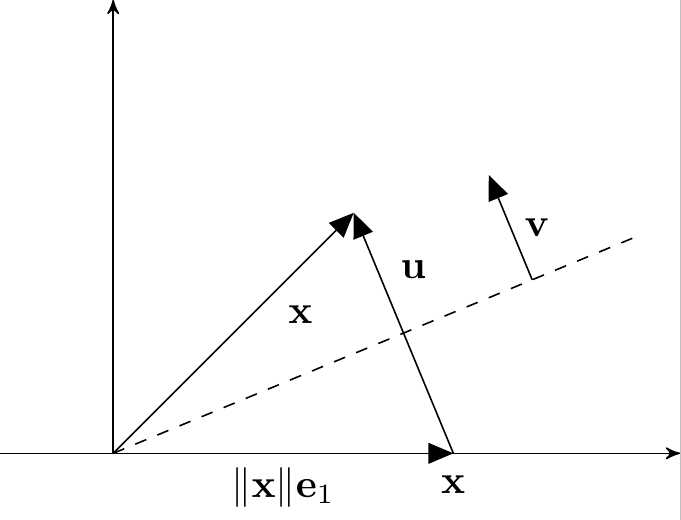

The Householder matrix is a linear transformation that performs this reflection and is calculated using


$$H = I - 2\frac{\mathbf{u} \mathbf{u}^T}{\mathbf{u} \cdot \mathbf{u}},$$


where


$$\mathbf{u} = \mathbf{x} - \|\mathbf{x}\| \mathbf{e}_1.$$


If $\mathbf{x}$ is nearly parallel to $\mathbf{e}_1$ then the value of $\mathbf{u}\cdot \mathbf{u}$ is close to zero and computational rounding errors can occur. However, we can choose to reflect $\mathbf{x}$ so that it is parallel to $\mathbf{e}$ but pointing in the opposite direction.

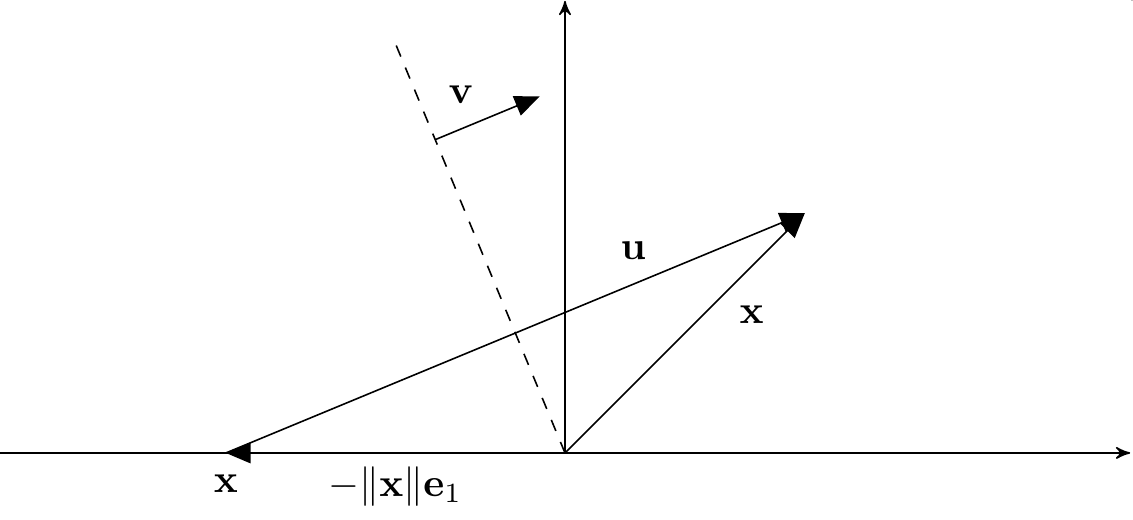

In the diagram above $\mathbf{x}$ is to be transformed to $\mathbf{x}^*$ then


$$\mathbf{u} = \mathbf{x} + \| \mathbf{x} \| \mathbf{e}_1,$$


so in order to always reflect in the direction that gives the largest value of $\|\mathbf{u}\|$ we use


$$\mathbf{u} = \mathbf{x} + \text{sign}(x) \| \mathbf{x} \| \mathbf{e}_1,$$


where 


$$\text{sign}(x) = \begin{cases} 1, & x \geq 0, \\ -1, & x < 0. \end{cases}$$


To calculate the QR decomposition of an $m\times n$ matrix $A$ we let $Q=I_m$ and $R=A$ and use Householder transformations to transform each of the column vectors in $R$ so that they are parallel to the basis vector $\mathbf{e}_1$. To do this we first calculate $\mathbf{u}$ using


$$\mathbf{u} = \mathbf{r}_1 + \text{sign}(r_{11}) \|\mathbf{r}_1\| \mathbf{e}_1.$$


and then we calculate the Householder matrix


$$H = I_m - 2 \frac{\mathbf{u} \mathbf{u}^T}{\mathbf{u} \cdot \mathbf{u}}.$$


The Householder transformation is applied to $R$ and $Q$ as follows


$$R = HR = \pmatrix{ r_{11} & r_{12} & r_{13} & \cdots & r_{1n} \cr 0 & r_{12} & r_{13} & \cdots & r_{2n} \cr 0 & r_{32} & r_{33} & \cdots & r_{3n} \cr \vdots & \vdots & \vdots & \ddots & \vdots \cr 0 & r_{m2} & r_{m3} & \cdots & r_{mn}}, \\ Q = QH.$$


So the first column of $R$ is now parallel to $\mathbf{e}_1$ in $\mathbb{R}^m$. We now need to transform the second column of $R$, without changing the first row and column, so that it is parallel to $\mathbb{e}_1$ in $\mathbb{R}^{m-1}$. Therefore we apply a Householder transformation to the matrix formed by omitting the first row and column of $R$. 

Calculate the Householder matrix for the second column of $R$


$$\mathbf{u} = \mathbf{r}_2 + \text{sign}\left(r_{22} \right) \| \mathbf{r}_2 \| \mathbf{e}_1, \\ H = I_{m-1} - 2 \frac{\mathbf{u} \mathbf{u}^T}{\mathbf{u} \cdot \mathbf{u}}.$$


Here $H$ is an $m-1 \times m-1$ matrix so we add the first row and column of the identity matrix to $H$ to ensure that it is and $m \times m$ matrix, i.e.,


$$H_2 = \pmatrix{ 1 & 0 & \cdots & 0 \cr 0 & & & \cr \vdots & & H \cr 0 & },$$


and this transformation is applied to $R$ and $Q$


$$R = HR = \pmatrix{ r_{11} & r_{12} & r_{13} & \cdots & r_{1n} \cr 0 & r_{12} & r_{13} & \cdots & r_{2n} \cr 0 & 0 & r_{33} & \cdots & r_{3n} \cr \vdots & \vdots & \vdots & \ddots & \vdots \cr 0 & 0 & r_{m3} & \cdots & r_{mn}}, \\ Q = QH.$$


This process is repeated for all columns in $R$ so that it is an upper triangular matrix. The $Q$ matrix is the product of all of the individual Householder transformations and is an orthonormal matrix.

#### Example 18

Calculate the QR decomposition of the following matrix using the Householder transformations

#### Example 19

The function qr_hh which is defined in the Functions section at the bottom of this page calculates the QR decomposition of the matrix `A` using Householder transformations. Note that we need to define our own function `mysign` to calculate the $\text{sign}(x)$ since MATLAB's `sign` function assumes $\text{sign}(0)=0$. 

The code below uses the function `qr_hh` to calculate the QR decomposition of the matrix $A$ in example 14.

% Define matrix A
A = [ -1, -1, 1 ;
      1, 3, 3 ;
      -1, -1, 5 ;
      1, 3, 7 ];

% Calculate QR decomposition
[Q, R] = qr_hh(A);

% Output and check results
for i = 1 : 1
    A
    Q
    R
    QR = Q * R
    QTQ = Q' * Q
end

A =     -1    -1     1
     1     3     3
    -1    -1     5
     1     3     7


Q =    -0.5000   -0.5000    0.5000    0.5000
    0.5000   -0.5000    0.5000   -0.5000
   -0.5000   -0.5000   -0.5000   -0.5000
    0.5000   -0.5000   -0.5000    0.5000


R =     2.0000    4.0000    2.0000
   -0.0000   -2.0000   -8.0000
    0.0000   -0.0000   -4.0000
    0.0000    0.0000         0


QR =    -1.0000   -1.0000    1.0000
    1.0000    3.0000    3.0000
   -1.0000   -1.0000    5.0000
    1.0000    3.0000    7.0000


QTQ =     1.0000   -0.0000    0.0000         0
   -0.0000    1.0000    0.0000   -0.0000
    0.0000    0.0000    1.0000         0
         0   -0.0000         0    1.0000


### Rounding errors in calculating QR decomposition

As with all numerical techniques, the two QR decomposition methods shown here are prone to computational rounding errors, especially since they both use square root calculations. The matrix $Q$ is orthogonal so the dot product of each column of $Q$ with all other columns should be equal to zero. We can use this to check the **loss of orthogonality** in our results. 

Defining an orthogonality error $e_j$ for a column vector $\mathbf{q}_j$ from $Q$ such that


$$e_j = \max_{1 \leq i < j} | \mathbf{q}_j \cdot \mathbf{q}_i |, \qquad j = 1, \ldots, n,$$


then non-zero values of $e_j$ indicates that we have lost some orthogonality due to computational rounding errors. 

The program below generates a random $100 \times 100$ matrix $A$ and calculates the QR decomposition using the Gram-Schmidt process and Householder transformations and plots the orthogonality errors. The function orthogonality_error is defined in the Functions section at the bottom of the page.

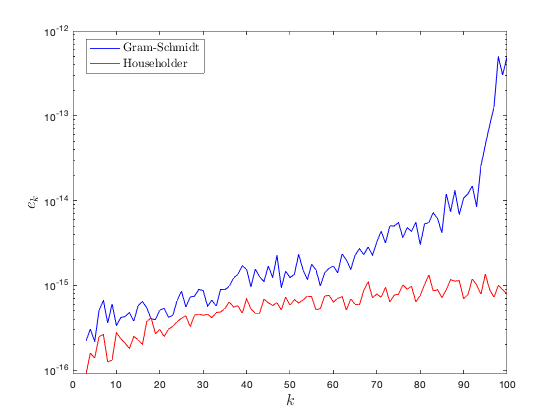

% Generate random 50x50 matrix A
rng(0)
A = randi(5, 100);

% Calculate the QR decomposition of A using the Gram-Schmidt process
% and Householder transformations
[Q1, ~] = qr_gs(A);
[Q2, ~] = qr_hh(A);

% Calculate orthogonality errors
e1 = orthogonality_error(Q1);
e2 = orthogonality_error(Q2);

% Plot orthogonality errors
semilogy(1:length(e1), e1, 'b-', 1:length(e1), e2, 'r-')

xlabel("$k$", "FontSize", 16, "Interpreter", "latex")
ylabel("$e_k$", "FontSize", 16, "Interpreter", "latex")
leg = legend("Gram-Schmidt", "Householder");
set(leg, "FontSize", 12, "Interpreter", "latex", "Location", "best")

Here we can see that the loss of orthogonality using Householder QR decomposition remains fairly constant the same cannot be said of the Gram-Schmidt QR decomposition where the loss of orthogonality increases as we reach the end columns of Q. We would expect this to increase further as the size of the matrix $A$ increases.

## Summary

- LU decomposition factorises a square matrix in the product of a lower triangular matrix $L$ and an upper triangular matrix $U$.

- Crout's method is used to solve a system of linear equations using LU decomposition by apply forward and back substitution.

- Partial pivoting ensures that the pivot element has a larger absolute value than the elements in the column below the pivot. This eliminates the problems caused when the pivot element is small resulting in computational rounding errors.

- Cholesky decomposition can be applied to factorise a positive definite matrix into the product of a lower triangular matrix $L$ and its transpose. Cholesky decomposition of a $n\times n$ matrix requires fewer operations than the equivalent LU decomposition.

- QR decomposition can be applied to factorise an $m\times n$ matrix into the product of an orthogonal matrix $Q$ and an $n\times n$ upper triangular matrix $R$. QR decomposition can be calculated using the Gram-Schmidt where an orthonormal basis is determined by recursively subtracting the vector projection of non-orthogonal vectors onto known basis vectors or using Householder transformations which recursively applies a linear transformation to the columns of $A$ to reflect them onto the basis vector $\mathbf{e}_1$.

- QR decomposition can be used to calculate a solution to an overdetermined system when the number of equations is bigger than the number of unknowns.

- The advantage of using decomposition methods for solving systems of linear equations is that a change in the constant values do not require a recalculation of the decomposition as opposed to [Gaussian elimination](https://en.wikipedia.org/wiki/Gaussian_elimination).

## Exercises

1. Solve the following systems of linear equations using LU decomposition using a pen and calculator.

    (a)


$$2x_1 + 3x_2 - x_3 = 4, \\
4x_1 + 9x_2 - x_3 = 18, \\
\qquad 3x_2 + 2x_3 = 11.$$
                

    (b)    


$$3x_1 + 9x_2 + 5x_3 = 20, \\
 \,\,\,\,   x_1 + 2x_2 + 2x_3 = 3, \\
    2x_1 + 4x_2 + 5x_3 = 4.$$
        

    (c)    


$$\qquad \,\,\,x_1 + 3x_3 + 2x_4 = 21, \\
    3x_1 - 2x_2 + 5x_3 + x_4 = 28, \\
    4x_1 - x_2 - 2x_3 - 3x_4 = -12, \\
   \qquad \qquad \,\,\, 2x_2 + 3x_4 = 13.$$
    

    (d)      


$$\,\,\,\,\,\,x_1 + 5x_2 + 2x_3 + 2x_4 = -10, \\
\quad\,\,\,\,    -2x_1 - 4x_2 + 2x_3 = 10, \\
\quad\,\,    3x_1 + x_2 - 2x_3 - x_4 = -2, \\
    -3x_1 - 3x_2 + 4x_3 - x_4 = 4.$$


2. Solve the systems from question 1 using LU decomposition with partial pivoting using a pen and calculator.

3. Solve the following systems of linear equations using Cholesky decomposition using a pen and calculator.

    (a)


$$\,\,\,\,16x_1 + 16x_2 + 4x_3 = -8, \\
    16x_1 + 25x_2 + 10x_3 = -47, \\
\quad     4x_1 + 10x_2 + 6x_3 = -30.$$


    (b)


$$\quad 4x_1 + 2x_2 + 8x_3 = 36, \\
    2x_1 + 17x_2 + 20x_3 = 50, \\
    8x_1 + 20x_2 + 41x_3 = 122.$$


    (c)


$$\qquad \qquad \,9x_1 - 9x_2 - 6x_4 = 12, \\
    -9x_1 + 25x_2 + 8x_3 - 10x_4 = -116, \\
 \qquad \qquad \,   8x_2 + 8x_3 - 2x_4 = -58, \\
    -6x_1 - 10x_2 - 2x_3 + 33x_4 = 91.$$


    (d)


$$\qquad\,\,\,\,\, x_1 + 5x_2 - x_3 + 2x_4 = 14, \\
\,\,\,\,\,    5x_1 + 29x_2 + 3x_3 + 12x_4 = 82, \\
\,    -x_1 + 3x_2 + 42x_3 - 13x_4 = 40, \\
    2x_1 + 12x_2 - 13x_3 + 39x_4 = -34.$$


4. Calculate the QR decomposition of the coefficient matrix for the following systems using the Gram-Schmidt process with a pen and calculator.

    (a)


$$x_1 + x_2 = 9, \\
\,\,\,\,\,\,    -x_1 = -5.$$


    (b)


$$6x_1 + 6x_2 + x_3 = 3, \\
    3x_1 + 6x_2 + x_3 = 0, \\
\,\,\,\,    2x_1 + x_2 + x_3 = 4.$$


    (c)


$$\,\,\,\,x_1 + 2x_2 + x_3 = 1, \\
    x_1 + 4x_2 + 3x_3 = 7, \\
    x_1 - 4x_2 + 6x_3 = -6, \\
 \,\,\,\,   x_1 + 2x_2 + x_3 = -1.$$


5. Repeat question 4 using Householder transformations.

6. Calculate the solutions to the linear systems in question 4 using QR decomposition.

7. Check your solutions to questions 1 to 4 using Python.

## Functions

The various functions used in this page are defined in this section.

#### LU decomposition

function [L, U] = lu_decomp(A)

% Calculates the LU decomposition of the square matrix A

% Initialise L and U
ncols = size(A, 1);
L = eye(ncols);
U = zeros(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Calculate u_ij for i < = j
    for i = 1 : j
        for k = 1 : i - 1
            U(i, j) = U(i, j) + L(i, k) * U(k, j);
        end
        U(i, j) = A(i, j) - U(i, j);
    end
    
    % Calculate l_ij for i > j
    for i = j + 1 : ncols
        for k = 1 : j - 1
            L(i, j) = L(i, j) + L(i, k) * U(k, j);
        end
        L(i, j) = (A(i, j) - L(i, j)) / U(j, j);
    end
end

end

#### Forward substitution

function x = forward_sub(L, b)

% Calculates the solution to Lx = b where L is a lower triangular matrix
% using forward substitution

ncols = size(L, 2);
x = zeros(ncols, 1);
for i = 1 : ncols
    for j = 1 : i - 1
        x(i) = x(i) + L(i, j) * x(j);
    end
    x(i) = (b(i) - x(i)) / L(i, i);
end

end

#### Back substitution

function x = back_sub(U, b)

% Calculates the solution to Ux = b where U is an upper triangular matrix
% using back substitution

ncols = size(U, 2);
x = zeros(ncols, 1);
for i = ncols : -1 : 1
    for j = i : ncols
        x(i) = x(i) + U(i, j) * x(j);
    end
    x(i) = (b(i) - x(i)) / U(i, i);
end

end

#### Crout's method

function x = crout(L, U, b)

% Calculates the solution to the system of linear equations LUx=b using 
% Crouts method

% Solve Ly = b using forward substitution
y = forward_sub(L, b);

% Solve Ux = y using back substitution
x = back_sub(U, y);

end

#### Partial pivoting

function P = partial_pivot(A)

% Applies partial pivoting to A and returns the permutation matrix P

ncols = size(A, 1);
P = eye(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Loop for max pivot
    maxpivot = A(j, j);
    k = j;
    for i = j : ncols
        if abs(A(i,j)) > abs(maxpivot)
            maxpivot = A(i, j);
            k = i;
        end
    end
    
    % Swap pivot row with max pivot row
    temp = P(j, :);
    P(j, :) = P(k, :);
    P(k, :) = temp;
end

end

#### Cholesky decomposition

function L = cholesky(A)

% Calculates the Cholesky decomposition of a positive definite matrix A

ncols = size(A, 1);
L = zeros(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Calculate main diagonal element
    for k = 1 : j - 1
        L(j, j) = L(j, j) + L(j, k) ^ 2;
    end
    L(j, j) = sqrt(A(j, j) - L(j, j));
    
    % Calculate lower triangular elements
    for i = j + 1 : ncols
        for k = 1 : j - 1
            L(i, j) = L(i, j) + L(i, k) * L(j, k);
        end
        L(i, j) = (A(i, j) - L(i, j)) / L(j, j);
    end
end

end

#### QR decomposition using the Gram-Schmidt process

function [Q, R] = qr_gs(A)

% Calculates the QR decomposition of the m x n matrix A using the 
% Gram-Schmidt process

ncols = size(A, 2);
R = zeros(ncols);
Q = zeros(size(A));

% Loop through columns of A
for j = 1 : ncols
    for i = 1 : j - 1
        R(i, j) = dot(Q(:, i), A(:, j));
        Q(:, j) = Q(:, j) + R(i, j) * Q(:, i);
    end
    Q(:, j) = A(:, j) - Q(:, j);
    R(j, j) = norm(Q(:, j));
    Q(:, j) = Q(:, j) / R(j, j);
end

end

#### QR decomposition using Householder transformations

function [Q, R] = qr_hh(A)

% Calculates the QR decomposition of the m x n matrix A using 
% Householder transformations

[nrows, ncols] = size(A);
Q = eye(nrows);
R = A;

% Loop through the columns of A
for i = 1 : ncols
    
    % Calculate Householder matrix
    u = R(i:end, i) + mysign(R(i, i)) * norm(R(i:end, i)) * [ 1 ; zeros(nrows - i, 1) ];
    H = eye(nrows);
    H(i:end, i:end) = eye(nrows + 1 - i) - 2 * (u * u') / (u' * u);
    
    % Apply Householder transformation to R and update Q
    Q = Q * H;
    R = H * R;
end

end

function y = mysign(x)

if x >= 0
    y = 1;
else
    y = -1;
end

end

#### Orthogonality errors

function e = orthogonality_error(Q)

% Calcualte the maximum orthogonality error the columns of an 
% orthogonal matrix Q

ncols = size(Q, 2);
e = zeros(ncols, 1);
for j = 2 : ncols
    for i = 1 : j - 1
        e(j) = max(e(j), abs(dot(Q(:, i), Q(:, j))));
    end
end

end